%Oncology

clc; clear; close all;

%Solve the system and visualize the system of ODEs %

% Define parameter values %
a1 = 0.5;  
b = 0.02;  
a2 = 0.1;  
alpha1 = 0.05; 
r1 = 0.02; 
r2 = 0.1;  
I0 = 1.0;  
h = 10;    
mu = 0.1;  
beta1 = 0.03; 
c = 0.6;   
d = 0.02;  
alpha2 = 0.04; 
beta2 = 0.02;  

% Initial conditions %
N0 = 10;
L0 = 5;
T0 = 2;
y0 = [N0; L0; T0];

% Time span %
tspan = [0 100];

% Solve using ode45 %
[t, y] = ode45(@(t, y) systemODEs(t, y, a1, b, a2, alpha1, r1, r2, I0, h, mu, beta1, c, d, alpha2, beta2), tspan, y0);

% Extract solutions %
N = y(:,1);
L = y(:,2);
T = y(:,3);

% Visualization of the system of equations %
figure;
axis off;

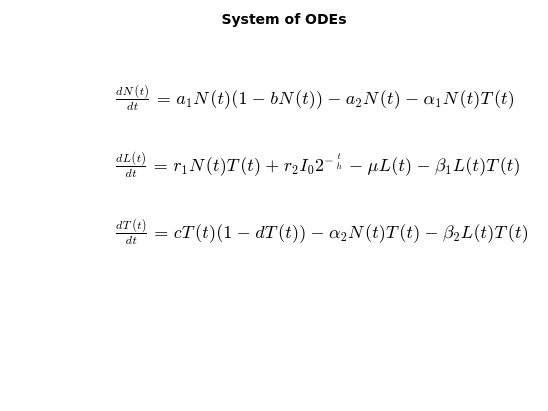


% Define the system of equations %
eq1 = '$\frac{dN(t)}{dt} = a_1 N(t)(1 - bN(t)) - a_2 N(t) - \alpha_1 N(t) T(t)$';
eq2 = '$\frac{dL(t)}{dt} = r_1 N(t) T(t) + r_2 I_0 2^{-\frac{t}{h}} - \mu L(t) - \beta_1 L(t) T(t)$';
eq3 = '$\frac{dT(t)}{dt} = c T(t) (1 - d T(t)) - \alpha_2 N(t) T(t) - \beta_2 L(t) T(t)$';

% Render the equations to a figure %
text(0.1, 0.8, eq1, 'Interpreter', 'latex', 'FontSize', 14);
text(0.1, 0.6, eq2, 'Interpreter', 'latex', 'FontSize', 14);
text(0.1, 0.4, eq3, 'Interpreter', 'latex', 'FontSize', 14);

title('System of ODEs');

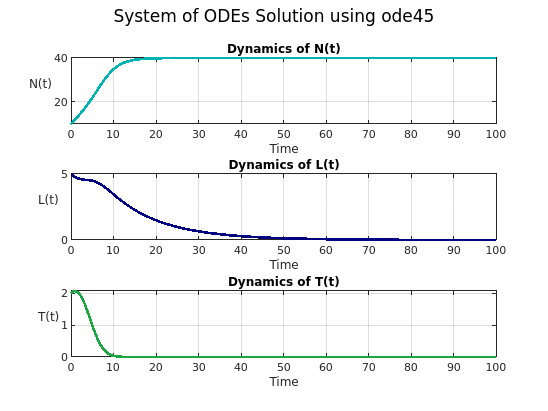


% Plot the results %
figure;
subplot(3,1,1);
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2); 
xlabel('Time'); ylabel('N(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of N(t)');
grid on;

subplot(3,1,2);
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2); 
xlabel('Time'); ylabel('L(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of L(t)');
grid on;

subplot(3,1,3);
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2); 
xlabel('Time'); ylabel('T(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of T(t)');
grid on;

sgtitle('System of ODEs Solution using ode45');

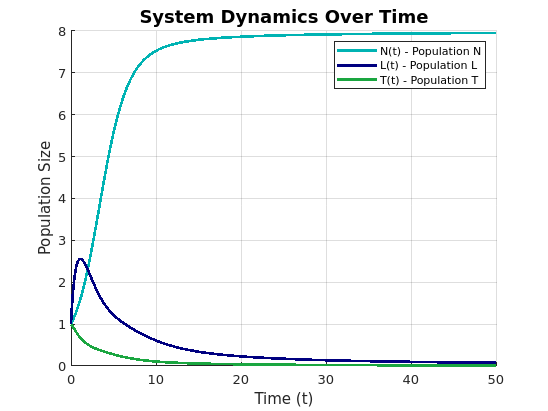


% Customized plots with different parameters %

% Define parameters
a1 = 1.0; b = 0.1; a2 = 0.2; alpha1 = 0.3;
r1 = 0.4; r2 = 0.5; I0 = 10; h = 1.0;
mu = 0.6; beta1 = 0.7; c = 0.8; d = 0.9;
alpha2 = 0.1; beta2 = 0.2;

% Define time span and initial conditions %
tspan = [0 50]; % Time range
y0 = [1; 1; 1]; % Initial conditions for N, L, and T

% Solve the system using ode45 %
[t, y] = ode45(@(t, y) systemODEs(t, y, a1, b, a2, alpha1, r1, r2, I0, h, mu, beta1, c, d, alpha2, beta2), tspan, y0);

% Extract the solution for N, L, and T %
N = y(:, 1);
L = y(:, 2);
T = y(:, 3);

% Create the plots %
figure;
hold on;
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2); 
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2); 
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2);

xlabel('Time (t)', 'FontSize', 12);
ylabel('Population Size', 'FontSize', 12);
title('System Dynamics Over Time', 'FontSize', 14);
legend('N(t) - Population N', 'L(t) - Population L', 'T(t) - Population T');
grid on;


% Display the system of equations %
equations = [
    '$\frac{dN}{dt} = a_1 N(1 - bN) - a_2 N - \alpha_1 N T$';
    '$\frac{dL}{dt} = r_1 N T + r_2 I_0 2^{-\frac{t}{h}} - \mu L - \beta_1 L T$';
    '$\frac{dT}{dt} = c T(1 - d T) - \alpha_2 N T - \beta_2 L T$'
];

Error using vertcat
Dimensions of arrays being concatenated are not consistent.


annotation('textbox', [0.15, 0.8, 0.7, 0.15], 'String', equations, 'Interpreter', 'latex', 'FontSize', 12, 'EdgeColor', 'none');


function dydt = systemODEs(t, y, a1, b, a2, alpha1, r1, r2, I0, h, mu, beta1, c, d, alpha2, beta2)
    N = y(1);
    L = y(2);
    T = y(3);
    
    dNdt = a1 * N * (1 - b * N) - a2 * N - alpha1 * N * T;
    dLdt = r1 * N * T + r2 * I0 * 2^(-t / h) - mu * L - beta1 * L * T;
    dTdt = c * T * (1 - d * T) - alpha2 * N * T - beta2 * L * T;
    
    dydt = [dNdt; dLdt; dTdt];
end